# A simulation of a standard BB84 pass.

To make BB84 work, a (low) 100km orbit is used

## 1. Choose parameters

wavelength=780;                                                            %wavelength is measured in nm
transmitter_telescope_diameter=0.1;                                        %diameters are measured in m
receiver_telescope_diameter=1;                                           
time_gate_width=1E-9;                                                      %times are measured in s
spectral_filter_width=10;                                                  %consistent with wavelength, spectral width is measured in nm

## 2. Construct components

%2.1 Satellite
%2.1.1 Source
Transmitter_Source=components.Source(wavelength,...
                                    'Repetition_Rate',1E8,...
                                    'MPN_Signal',0.1);                %we use default values to simplify this example

%2.1.2 Transmitter telescope
Transmitter_Telescope=components.Telescope(transmitter_telescope_diameter);           %do not need to specify wavelength as this will be set by satellite object

%2.1.3 Construct satellite
SimSatellite=nodes.Satellite(Transmitter_Telescope,...
                        'Source',Transmitter_Source,...
                        'LLAT',[55.909723, -3.319995, 500000, 1]);

%2.2 Ground station
%2.2.1 Detector
Detector=components.Detector(wavelength,...
                            Transmitter_Source.repetition_rate,...
                            time_gate_width,...
                            spectral_filter_width,...
                            'Preset','PerkinElmer');
%need to provide repetition rate in order to compute QBER and loss due to
%time gating

%2.2.2 Receiver telescope
Receiver_Telescope=components.Telescope(receiver_telescope_diameter);

%2.2.3 construct ground station, use Heriot-Watt as an example
SimGround_Station=nodes.GroundStation(Receiver_Telescope,...
                                'Detector',Detector,...
                                'LLA',[55.909723, -3.319995, 10],...
                                'Name','Heriot-Watt');

## 3 run and plot simulation

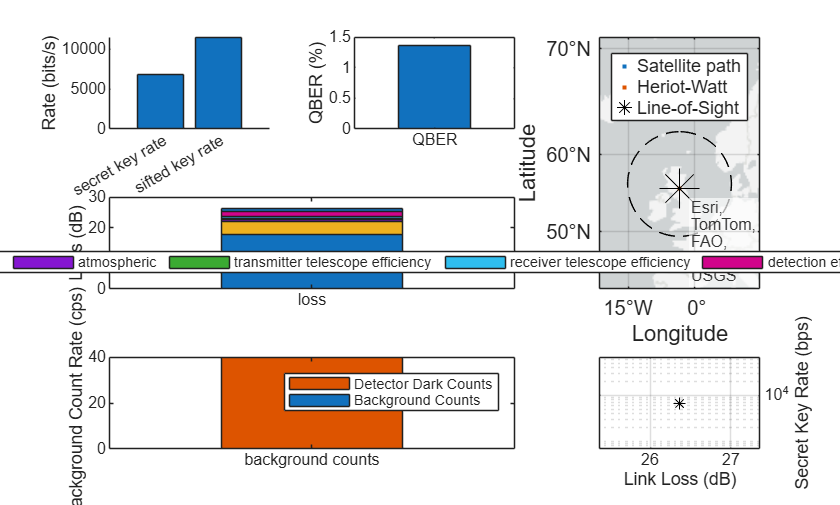

%3.1 run simulation
Result=nodes.qkdPassSimulation(SimGround_Station,SimSatellite,protocol.BB84);
%3.2 plot results
Result.plot();